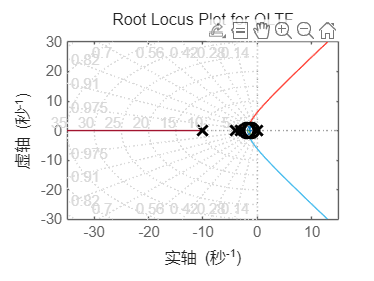

% 定义开环传递函数
num = [1, 3, 2]; % 分子：(s+1)(s+2) = s^2 + 3s + 2
den = poly([0, 0, -3, -4, -10]); % 分母：s^2(s+3)(s+4)(s+10)
G = tf(num, den);

% 绘制根轨迹
figure;
rlocus(G);
title('Root Locus Plot for OLTF');
hold on;

% 标注极点和零点
poles = pole(G);
zeros = zero(G);
plot(real(poles), imag(poles), 'kx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Poles');
plot(real(zeros), imag(zeros), 'ko', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Zeros');

% 添加网格
sgrid;


% 计算断开点（通过特征方程的导数）
syms s K
num_s = poly2sym(num, s);
den_s = poly2sym(den, s);
K_s = -den_s / num_s; % K 作为 s 的函数
dK_ds = simplify(diff(K_s, s)); % 对 K 求导
breakaway_eq = dK_ds == 0; % 导数为 0 的点

% 求解断开点
breakaway_points = double(solve(breakaway_eq, s, 'Real', true)); % 求解实根
fprintf('Raw Breakaway Points from solve: %s\n', mat2str(breakaway_points));

Raw Breakaway Points from solve: [0;-1.47708817687325;-3.41660659370753;-7.64137187470768]



% 筛选断开点（只保留在实轴上且在极点和零点之间的点）
if ~isempty(breakaway_points)
    % 确定实轴范围：从最左边的极点到最右边的零点
    min_pole = min(real(poles));
    max_zero = max(real(zeros));
    breakaway_points = breakaway_points(breakaway_points >= min_pole & breakaway_points <= max_zero);
    fprintf('Filtered Breakaway Points: %s\n', mat2str(breakaway_points));
else
    fprintf('No valid breakaway points found using symbolic solve.\n');
    % 备用方法：手动检查可能的断开点范围（例如在 0 到 -3 之间）
    s_range = linspace(-3, 0, 1000); % 在极点 0 和 -3 之间搜索
    K_vals = -polyval(den, s_range) ./ polyval(num, s_range);
    [~, idx] = min(abs(diff(K_vals))); % 找到 K 变化最小的点
    breakaway_points = s_range(idx);
    fprintf('Estimated Breakaway Point (numerical): %f\n', breakaway_points);
end

Filtered Breakaway Points: [-1.47708817687325;-3.41660659370753;-7.64137187470768]



% 标注断开点
if ~isempty(breakaway_points)
    plot(breakaway_points, zeros(size(breakaway_points)), 'r*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Breakaway Points');
else
    fprintf('No breakaway points to plot.\n');
end

索引超过数组元素的数量。索引不能超过 2。


% 计算虚轴交叉点
[K, r] = rlocus(G); % 获取根轨迹的增益和极点位置
imaginary_crossings = [];
for i = 1:length(K)
    poles_at_K = r(:, i);
    idx = abs(real(poles_at_K)) < 1e-3 & abs(imag(poles_at_K)) > 1e-3;
    if any(idx)
        crossings = imag(poles_at_K(idx));
        imaginary_crossings = [imaginary_crossings; crossings(1)]; % 取第一个交叉点
    end
end
if ~isempty(imaginary_crossings)
    fprintf('Imaginary Axis Crossings at: j%s\n', mat2str(imaginary_crossings));
    plot(0, imaginary_crossings, 'g^', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Imaginary Axis Crossing');
end

% 计算渐近线
n = length(poles); % 极点数量
m = length(zeros); % 零点数量
asymp_count = n - m; % 渐近线数量
sum_poles = sum(poles);
sum_zeros = sum(zeros);
centroid = (sum_poles - sum_zeros) / (n - m);
fprintf('Asymptote Centroid: %f\n', real(centroid));
angles = (pi * (2 * (0:(asymp_count-1)) + 1)) / (n - m);
fprintf('Asymptote Angles (degrees): %s\n', mat2str(rad2deg(angles)));

% 添加图例
legend('show');
hold off;

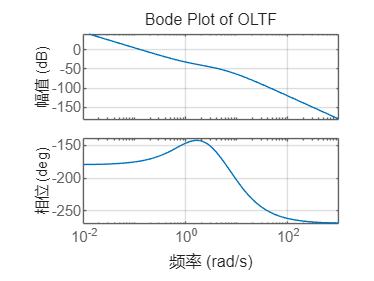

% Define the transfer function
num = [1, 3, 2]; % Numerator: (s+1)(s+2) = s^2 + 3s + 2
den = poly([0, 0, -3, -4, -10]); % Denominator: s^2(s+3)(s+4)(s+10)
G = tf(num, den);

% Generate the Bode plot
figure;
bode(G);
grid on;
title('Bode Plot of OLTF');

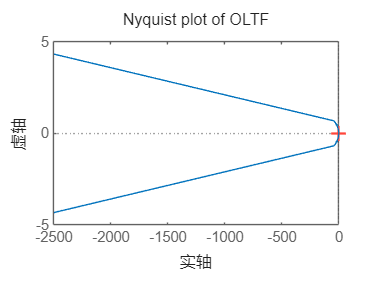

nyquist(G)
title('          ')

% Define the transfer function
num = [1, 3, 2];           % Numerator: (s+1)(s+2) = s^2 + 3s + 2
den = poly([0, 0, -3, -4, -10]); % Denominator: s^2(s+3)(s+4)(s+10)
G = tf(num, den);          % Open-loop transfer function

% Compute margins
[GM, PM, GMFrequency, PMFrequency] = margin(G);

% Compute Delay Margin
DM = PM / (180 * pi * PMFrequency); % PM in degrees, convert to radians

% Display results
fprintf('Gain Margin (GM): %.4f (linear), %.4f dB\n', GM, 20*log10(GM));

Gain Margin (GM): 557.5962 (linear), 54.9264 dB


fprintf('GM Frequency: %.4f rad/s\n', GMFrequency);

GM Frequency: 6.1756 rad/s


fprintf('Phase Margin (PM): %.4f degrees\n', PM);

Phase Margin (PM): 6.0247 degrees


fprintf('PM Frequency: %.4f rad/s\n', PMFrequency);

PM Frequency: 0.1297 rad/s


fprintf('Delay Margin (DM): %.4f seconds\n', DM);

Delay Margin (DM): 0.0821 seconds


fprintf('DM Frequency: %.4f rad/s\n', PMFrequency);

DM Frequency: 0.1297 rad/s



% Stability check
if PM > 0 && GM > 1
    fprintf('The system is stable.\n');
else
    fprintf('The system is unstable or marginally stable.\n');
end

The system is stable.
